# Time series analysis: Wavelet transforms and coherence

LFPs oscillations represent the collective electrical activity of neuronal populations, reflecting their synchronized firing patterns across different frequency ranges. Time frequency and coherence analysis, can give insights into how oscillations correlates with the behavioral state of the animal and how different brain regions synchronize over certain frequency ranges. For instance, in the context of hippocampal LFP oscillations, analyzing spectrograms can reveal how theta and gamma oscillations are associated with learning, memory, and spatial navigation. Similarly, coherence analysis can reveal the coordinated activity between the hippocampus and other regions, such as the entorhinal cortex or prefrontal cortex, shedding light on their collaborative roles in learning and memory.

In this tutorial, we will see how to use wavelet transforms and wavelet coherence to investigate how the coherence and their oscillatory content of hippocampal and bla Lfps depend on the animal position and speed.

The analyses described in this section can be run by calling the following set of functions:

%Path to the directory where the data are stored
datadirpath = [filesep 'MATLAB Drive' filesep 'School' filesep 'Dataset' filesep 'Session1'];

%Load the default parameters for loading the data
loadparams = SetLoadParams(datadirpath);

%Load the behavioral data into a matlab structure.
Nav = LoaddataNav(loadparams);

%Load the Lfp data into a matlab structure.
Lfp = LoaddataLfp(loadparams, Nav.sampleTimes);

%define parameters for time frequency analysis
TFmapsparams = SetTFMapsParams(Nav,Lfp.Lfp_raw);

%estimate 2D maps of power and coherence across positions
TFMaps = TFMapsAnalysis(Nav, Lfp.Lfp_raw, TFmapsparams, Lfp.sampleTimes_raw);

### 4.1. Loading and preprocessing the behavioral and Lfp data

As usual, we first load and preprocess the behavioral and spiking data

%Path to the directory where the data are stored
datadirpath = [filesep 'MATLAB Drive' filesep 'School' filesep 'Dataset' filesep 'Session1'];

%Load the default parameters for loading the data
loadparams = SetLoadParams(datadirpath);

%Load the behavioral data into a matlab structure.
Nav = LoaddataNav(loadparams);

%Load the Lfp data into a matlab structure.
Lfp = LoaddataLfp(loadparams, Nav.sampleTimes);

### 4.2 Parameters for spectral analysis of Lfp signals

Defining a set of parameters needed before we compute the wavelet transforms and the corresponding maps

%Experimental condition over which time frequency analyses will be
%conducted
TFmapsparams.subset.Condition = [1 3 5];
TFmapsparams.subset.Condition_op = 'ismember';

%directions along X over which time frequency analyses will be conducted
TFmapsparams.subset.XDir = [-1 1];
TFmapsparams.subset.XDir_op = 'ismember';

%Minimum speed threshold over which time frequency analyses will be 
%conducted
TFmapsparams.subset.Spd =  2.5;
TFmapsparams.subset.Spd_op = '>=';

%Frequency range for TF analysis
TFmapsparams.freqrange = [1 200];

%Subset of signals in Lrep for which time-freuqency analysis will be
%performed
TFmapsparams.chidx = 1:size(Lfp.Lfp_raw,2);

%Sampling rate of the raw lfps
TFmapsparams.sampleRate_raw = 1 / mean(diff(Lfp.sampleTimes_raw));

%Sampling rate of the independent variables in Nav with which frequency
%power/coherence will be correlated to.
TFmapsparams.sampleRate = 1 / mean(diff(Nav.sampleTimes));

%Name of the independent variable used to map the response along X. Default
%is Xpos
TFmapsparams.Xvariablename = 'Xpos';

%Edges of position bins used to discretize X
TFmapsparams.Xbinedges = 0: 4: 100;

%Size of the gaussian window for smoothing place fields along X (in bins).
TFmapsparams.XsmthNbins = 1;

%Name of the independent variable used to map the response along Y. Default
%is XDir.
TFmapsparams.Yvariablename = 'XDir';

%Size of the gaussian window for smoothing place fields along Y (in bins).
TFmapsparams.YsmthNbins = 0;

%Edges of Y bins used to discretize Y
TFmapsparams.Ybinedges = [-2 0 2];

This set of parameters can be obtained by calling **SetTFMapsParams.m**

TFmapsparams = SetTFMapsParams(Nav, Lfp.Lfp_raw, Lfp.sampleTimes_raw);

### 4.3 Wavelet transform of hippocampal Lfp

Plot the 1D wavelet transform of the hippocampal Lfp for the first 2 seconds of the pre-run condition.

%Time when pre-run starts
timestart = Nav.sampleTimes(find(Nav.Condition == 1, 1, 'first'));

%Lfp indices of the first 2 seconds
tidx = find(Lfp.sampleTimes_raw >= timestart & Lfp.sampleTimes_raw <= timestart + 2);

%Sampling frequency of raw Lfp signals
rawFs = 1 / mean(diff(Lfp.sampleTimes_raw));

%Run the wavelet transform calculation using the cwt function of the
%wavelet toolbox, with a Morse wavelet family with the default parameters.
[wt,f,~,~] = cwt(Lfp.Lfp_raw(tidx, 1),'morse', rawFs);

%The output of cwt is complex numbers. We take the modulus of it, which
%represent the power
wt = abs(wt);

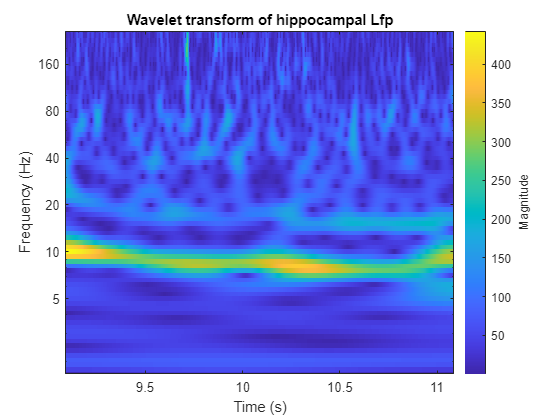

%Plotting the wavelet transform
figure;
imagesc(Lfp.sampleTimes_raw(tidx), f, wt);

%Scaling the Y axis correctly (be careful, the range of frequencies is
%on a log space and imagesc doesn't know about it
set(gca, 'Yscale', 'log', 'Ydir', 'normal', 'YTick', [5 10 20 40 80 160], 'Ylim', [min(f) max(f)]);

%Colorbar, labels, title
c = colorbar;
c.Label.String = 'Magnitude';
xlabel('Time (s)')
ylabel('Frequency (Hz)');
title('Wavelet transform of hippocampal Lfp')

### 4.4 Wavelet transform of hippocampal Lfp across positions

We would like to compute the variations of the Lfp oscillations across positions of the animal on the track.

Let's first select the time indices over which we want to map the spatial profile of the oscillations.

%Selecting time indices over which to perform the time frequency 
%decomposition, according to parameters defined in TFmapsparams.subset
tidx = true(size(Nav.Xpos));
pnames = fieldnames(TFmapsparams.subset);
fnames = fieldnames(Nav);
for i = 1:numel(pnames)
    if ismember(pnames{i},fnames)
        fn = str2func(TFmapsparams.subset.([pnames{i} '_op']));
        tidx = tidx & fn(Nav.(pnames{i}), TFmapsparams.subset.(pnames{i}));
    elseif ~strcmp(pnames{i}(end-2:end),'_op')
        warning('some fields of TFmapsparams.subset are not matching fields of Nav')
    end
end

%Selecting time indices where X and Y are in the range of bins
tidx = tidx &...
       Nav.Xpos >= TFmapsparams.Xbinedges(1) & Nav.Xpos <= TFmapsparams.Xbinedges(end) &...
       Nav.XDir >= TFmapsparams.Ybinedges(1) & Nav.XDir <= TFmapsparams.Ybinedges(end) &...
       ~isnan(Nav.Xpos) & ~isnan(Nav.XDir);
        
%Selecting signals to include in the analysis
chidx = 1:size(Lfp.Lfp_raw,2);

%Subsetting Lrep
Lsignal = Lfp.Lfp_raw(:,chidx);

%Numbre of channels to analyze
nch = size(Lsignal, 2);
        
%Sampling frequency of raw Lrep signals
rawFs = 1 / mean(diff(Lfp.sampleTimes_raw));

%Sampling frequency of independent variables
navFs = 1 / mean(diff(Nav.sampleTimes));

Although we could first start with by applying the wavelet transform to our entire signal before computing the spatial profile, this wouldn't be very efficient: first it would take a lot of time and memory to do so over more than 6 hrs of recording sampled at 600Hz; and the time spent by the animal on the track is only a fraction of this recording so we don't need to do the wavelet transform over all of it.

However, we do need some continuous chunks of data of reasonable length to get a good approximation over low frequencies. So, before running the wavelet transform, we have to perform the wavelet transform over those continuous periods and select time bins within the wavelet transform afterwards.

%Finding segments of data that are less than 300 seconds apart and merge
%them
brkwin = 2 * floor(300 * navFs /2) + 1;
tidxmerge = smooth(double(tidx), brkwin, 'moving') > 0;

startidx = find(diff(tidxmerge(brkwin:end)) > 0) + floor(brkwin/2);
endidx = find(diff(tidxmerge(1:end - brkwin + 1)) < 0) - floor(brkwin/2);
if startidx(1) > endidx(1) %if conditions were fulfilled when recoding started
    startidx = [1 ; startidx];
end
if startidx(end) > endidx(end) %if conditions were fulfilled when recoding stopped
    endidx = [endidx ; numel(Nav.sampleTimes)];
end

%Converting the indices from behavioral indices to raw Lfp indices
startidx_lfp = floor((startidx - 1) / navFs * rawFs + 1);
endidx_lfp = floor((endidx - 1) / navFs * rawFs + 1);

%Number of data segments
nseg = numel(startidx_lfp);

%Duration of segments
segduration = (endidx_lfp - startidx_lfp) / rawFs;

Now that we have the necessary segments, we can run the wavelet transform on each segment. We will also resample the returned wavelet transforms in the frequency domain (because they may not have the same frequencies) and in the time domain (because we don't need 600 Hz resolution once the power of the oscillation is computed).

%List of frequencies to resample the wavelet transform
fq_new = logspace(log10(TFmapsparams.freqrange(1)),log10(TFmapsparams.freqrange(2)),96);

%Initializing the final array of time x frequency wavelet transform,
%sampled according to Nav.sampleTimes.
wti = NaN(numel(Nav.sampleTimes), numel(fq_new), nch);

%Calculating the wavelet transform over the identified segments of data
for ich = 1:nch
    for k = 1:nseg
        %wavelet transform with Morse wavelet
        [wt,f,~,~] = cwt(Lsignal(startidx_lfp(k):endidx_lfp(k),ich),'morse',rawFs, 'FrequencyLimits', [fq_new(1) fq_new(end)]);

        %cwt returns frequencies from high to low. Flipping it up/down to avoid
        %confusions later.
        wt = flipud(wt);
        f = flipud(f);

        %Power of oscillations
        wt = abs(wt);

        %Time along the first dimension.
        wt = wt';

        %Saving wavelet transform into wtresp at the resolution
        t_old = Lfp.sampleTimes_raw(startidx_lfp(k):endidx_lfp(k));
        t_new = Nav.sampleTimes(startidx(k):endidx(k));
        wti(startidx(k):endidx(k),:,ich) = interp2(f, t_old, wt, fq_new, t_new);
    end
end

Plot the same first 10 seconds as before and check that everything is correct

%Time when pre-run starts
timestart = Nav.sampleTimes(find(Nav.Condition == 1, 1, 'first'));

%Lfp indices of the first 10 seconds
tidx = find(Nav.sampleTimes >= timestart & Nav.sampleTimes <= timestart + 2);

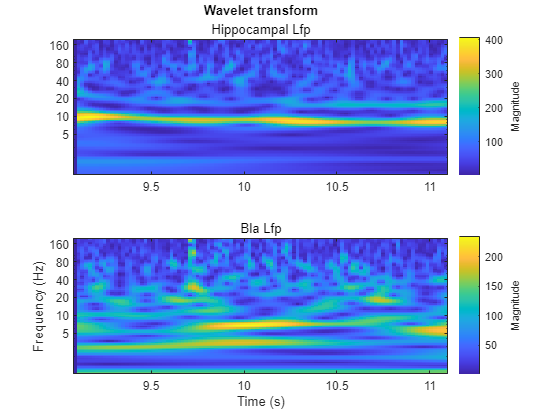


%Plotting the wavelet transform
figure;
Lfpnames = {'Hippocampal Lfp', 'Bla Lfp'};

for ich = 1:nch
    subplot(2,1,ich);
    imagesc(Nav.sampleTimes(tidx), f, wti(tidx,:,ich)');
    set(gca, 'Yscale', 'log', 'Ydir', 'normal', 'YTick', [5 10 20 40 80 160], 'Ylim', [min(f) max(f)]);
    c = colorbar;
    c.Label.String = 'Magnitude';
    subtitle(Lfpnames{ich});
end

%Colorbar, labels, title
subplot(2,1,nch);
xlabel('Time (s)')
ylabel('Frequency (Hz)');
subplot(2,1,1);
title('Wavelet transform')

Now we are ready to compute the spatial profile of the power at each frequency. We will use **MapsAnalysis.m **to do that, after adjusting accordingly the parameters.

%Defining parameters to compute spatial profiles
mapsparams = TFmapsparams;
mapsparams.cellidx = true(1, size(wti, 2));
mapsparams.nspk_th = -inf;

%Running place field analysis on the wavelet transform for each Lfp channel
wtMaps = cell(1,nch);
for ich = 1:nch
    wtMaps{ich} = MapsAnalysis(Nav, wti(:,:,ich), mapsparams);
end

These analyses can be run by calling **TFMapsAnalysis.m**.

%Default parameters for time-frequency map analysis
TFmapsparams = SetTFMapsParams(Nav, Lfp.Lfp_raw, Lfp.sampleTimes_raw);
%Computing maps on wavelet transforms
TFMaps = TFMapsAnalysis(Nav, Lfp.Lfp_raw, TFmapsparams, Lfp.sampleTimes_raw);

Plot the spatial profile of all fequencies, for both direction of travel. To your opitnion, are there frequencies tuned to positions?

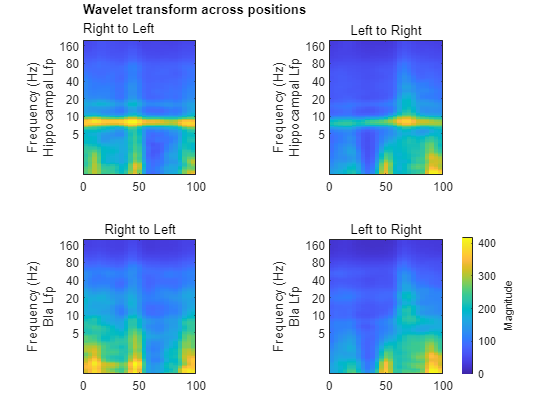

figure;

%Titles for directions
dirnames = {'Right to Left','Left to Right'};
Lfpnames = {'Hippocampal Lfp', 'Bla Lfp'};
ndir = 2;

%Plotting
for ich = 1:nch
    for idir = 1:ndir
        subplot(nch,ndir,(ich-1) * ndir + idir);
        imagesc(TFMaps.wtMaps{ich}.Xbincenters, TFMaps.fqbins, squeeze(TFMaps.wtMaps{ich}.map(:,idir,:)));
        set(gca, 'Ylim', [TFMaps.fqbins(1) TFMaps.fqbins(end)], 'Ydir', 'normal');
        set(gca, 'Yscale', 'log', 'Ytick',[5 10 20 40 80 160]);
        subtitle(dirnames{idir});
        ylabel({'Frequency (Hz)',Lfpnames{ich}});
        if ndir == 1 && ich == nch
            xlabel('Position (%)')
        end
        c = colorbar;
        c.Label.String = 'Magnitude';
        if idir ~= ndir || ich ~= nch
            colorbar('Visible','off');
        end
    end
end

%Title, label, etc
subplot(nch,ndir,1);
set(gca,'TitleHorizontalAlignment','left')
title('Wavelet transform across positions')

### 4.5 Wavelet coherence between hippocampal and bla Lfps

Compute and plot the wavelet coherence between bla and hpc Lfps over the first two seconds of the pre-run condition. You can use the function wcoherence from the wavelet toolbox.

%Time when pre-run starts
timestart = Nav.sampleTimes(find(Nav.Condition == 1, 1, 'first'));

%Lfp indices of the first 2 seconds
tidx = find(Lfp.sampleTimes_raw >= timestart & Lfp.sampleTimes_raw <= timestart + 2);

%Sampling frequency of raw Lfp signals
rawFs = 1 / mean(diff(Lfp.sampleTimes_raw));

%Run the wavelet coherence calculation using the wcoherence from the
%wavelet toolbox, using the default parameters.
[wc,~,f] = wcoherence(Lfp.Lfp_raw(startidx_lfp(k):endidx_lfp(k),1),Lfp.Lfp_raw(startidx_lfp(k):endidx_lfp(k),2),rawFs ...
                      , 'FrequencyLimits', [0 100]);

%The output of cwt is complex numbers. We take the modulus of it, which
%represent the power
wc = abs(wc);

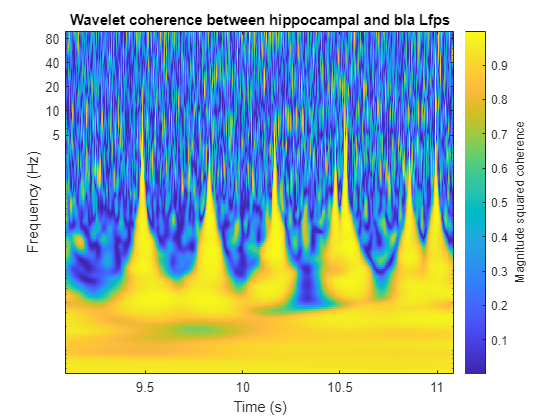

%Plotting the wavelet transform
figure;
imagesc(Lfp.sampleTimes_raw(tidx), f, wc);

%Scaling the Y axis correctly (be careful, the range of frequencies is
%on a log space and imagesc doesn't know about it
set(gca, 'Yscale', 'log', 'Ydir', 'normal', 'YTick', [5 10 20 40 80 160], 'Ylim', [min(f) max(f)]);

%Colorbar, labels, title
c = colorbar;
c.Label.String = 'Magnitude squared coherence';
xlabel('Time (s)')
ylabel('Frequency (Hz)');
title('Wavelet coherence between hippocampal and bla Lfps')

### 4.6 Coherence between hippocampus and bla across positions of the track

Do the same position profile analysis as with the wavelet transform, but using now the coherence between hpc and bla.

%List of frequencies to resample the wavelet coherence
fq_new = logspace(log10(TFmapsparams.freqrange(1)),log10(TFmapsparams.freqrange(2)),96);

%Initializing the final array of time x xfrequency wavelet transform
wci = NaN(numel(Nav.sampleTimes), numel(fq_new));

%Calculating the wavelet coherence over the identified segments of data
for k = 1:nseg
    %wavelet coherence with Morlet wavelet
    [wc,~,f] = wcoherence(Lfp.Lfp_raw(startidx_lfp(k):endidx_lfp(k),1),Lfp.Lfp_raw(startidx_lfp(k):endidx_lfp(k),2),rawFs, 'FrequencyLimits', [fq_new(1) fq_new(end)]);
    
    %wcoherence returns frequencies from high to low. Flipping it up/down to avoid
    %confusions later.
    wc = flipud(wc);
    f = flipud(f);

    %Power of oscillations
    wc = abs(wc);
    
    %Time along the first dimension.
    wc = wc';

    %flipping

    %Saving wavelet transform into wtresp at the resolution
    t_old = Lfp.sampleTimes_raw(startidx_lfp(k):endidx_lfp(k));
    t_new = Nav.sampleTimes(startidx(k):endidx(k));
    wci(startidx(k):endidx(k),:) = interp2(f, t_old, wc, fq_new, t_new);
end

%Compute the spatial profile of power across frequenciesby calling
%MapsAnalyses2D.
mapsparams = TFmapsparams;
mapsparams.cellidx = true(1, size(wci, 2));
mapsparams.nspk_th = -inf;

%Running place field analysis on the wavelet coherence
wcMaps = MapsAnalysis(Nav, wci, mapsparams);

These analyses on wavelet coherence are also run by **TFMapsAnalysis.m**.

%Default parameters for time-frequency map analysis
TFmapsparams = SetTFMapsParams(Nav, Lfp.Lfp_raw, Lfp.sampleTimes_raw);
%Computing maps on wavelet transforms
TFMaps = TFMapsAnalysis(Nav, Lfp.Lfp_raw, TFmapsparams, Lfp.sampleTimes_raw);

Plot the spatial profile of the Hpc-bla coherence, for both direction of travel.

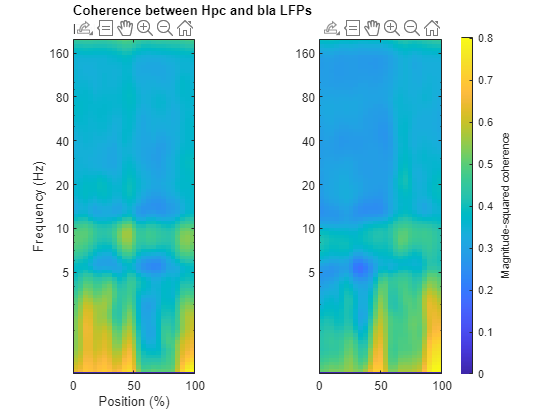

figure;

%Titles for directions
dirnames = {'Right to Left','Left to Right'};

%Plotting
for idir = 1:2
    subplot(1,2,idir);
    imagesc(TFMaps.wcMaps{1,2}.Xbincenters, TFMaps.fqbins, squeeze(TFMaps.wcMaps{1,2}.map(:,idir,:)));
    set(gca, 'Ylim', [TFMaps.fqbins(1) TFMaps.fqbins(end)], 'Ydir', 'normal');
    set(gca, 'Yscale', 'log', 'Ytick',[5 10 20 40 80 160]);
    subtitle(dirnames{idir});
    c = colorbar;
    c.Label.String = 'Magnitude-squared coherence';
    if idir == 1
        colorbar('Visible','off');
    end
end

%Title, label, etc
subplot(1,2,1)
xlabel('Position (%)');
ylabel('Frequency (Hz)');
set(gca,'TitleHorizontalAlignment','left')
title('Coherence between Hpc and bla LFPs')